# Propagation of EM wave

% Jonghwan Lee, 2023

## Constants and given values

clear;

c = 3e8;  % speed of light (m/s)

E0 = 2.0;  % amplitude
nu = 1e8;  % frequency
omega = 2*pi*nu;  % angular frequency
k_hat = [1 0 2] / norm([1 0 2]);  % unit vector of k

k = omega/c*k_hat  % k vector

k =     0.9366         0    1.8733


## Make a 2D array of E field magnitude.

Make a 2D grid of (x,z).

dz = 0.1;  % sampling interval [m]
z = -10:dz:10;
x = -5:dz:5;  % set dx = dz
[gx,gz] = ndgrid(x,z);
size(gx)  % check the size

ans =    101   201


gx

gx =    -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000   -5.0000
   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -4.9000   -

gz

gz =   -10.0000   -9.9000   -9.8000   -9.7000   -9.6000   -9.5000   -9.4000   -9.3000   -9.2000   -9.1000   -9.0000   -8.9000   -8.8000   -8.7000   -8.6000   -8.5000   -8.4000   -8.3000   -8.2000   -8.1000   -8.0000   -7.9000   -7.8000   -7.7000   -7.6000   -7.5000   -7.4000   -7.3000   -7.2000   -7.1000   -7.0000   -6.9000   -6.8000   -6.7000   -6.6000   -6.5000   -6.4000   -6.3000   -6.2000   -6.1000   -6.0000   -5.9000   -5.8000   -5.7000   -5.6000   -5.5000   -5.4000   -5.3000   -5.2000   -5.1000
  -10.0000   -9.9000   -9.8000   -9.7000   -9.6000   -9.5000   -9.4000   -9.3000   -9.2000   -9.1000   -9.0000   -8.9000   -8.8000   -8.7000   -8.6000   -8.5000   -8.4000   -8.3000   -8.2000   -8.1000   -8.0000   -7.9000   -7.8000   -7.7000   -7.6000   -7.5000   -7.4000   -7.3000   -7.2000   -7.1000   -7.0000   -6.9000   -6.8000   -6.7000   -6.6000   -6.5000   -6.4000   -6.3000   -6.2000   -6.1000   -6.0000   -5.9000   -5.8000   -5.7000   -5.6000   -5.5000   -5.4000   -5.3000   -5.2000   -

Make the 2D array of E field magnitude.

E = E0 * cos(k(1)*gx + k(2)*0 + k(3)*gz);  % y = 0 on the xz plane, t = 0

Plot the 2D array as an image.

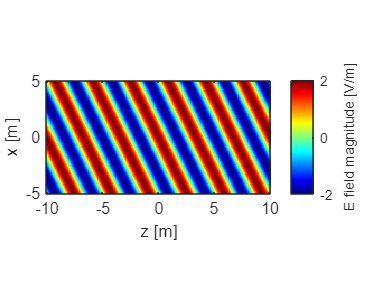

figure;  
imagesc(z, x, E);  % we don't use the transpose because imagesc() plots the first dimension of the 2D array (x here) in the vertical axis, and we want it in this example
ax = gca;
ax.YDir = 'normal';
ax.DataAspectRatio = [1 1 1];
ax.Colormap = jet;  % use the colormap of jet to clearly visualize the negative values in blue
ax.CLim = [-2 2];  % we know the E field magnitude should be between -2 and 2.
cb = colorbar;
cb.Label.String = 'E field magnitude [V/m]';
% cb.Label.Rotation = 270;  cb.Label.Position(1) = 3;
xlabel('z [m]');
ylabel('x [m]');

Plot the E field pattern at a few z positions.

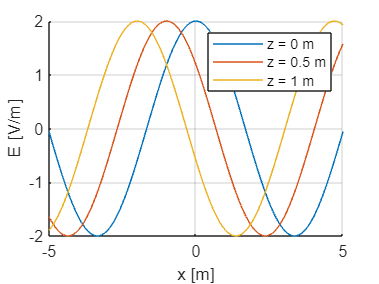

zs = [0 0.5 1];

figure;
clr = lines;
for iz=1:length(zs)
    z1 = zs(iz);  % the z value for each loop
    iz1 = find(z==z1);  % index of z for z1
    E1 = E(:,iz1);
    line(x,E1,'color',clr(iz,:));
end
grid on;
xlabel('x [m]');
ylabel('E [V/m]');
legend(compose('z = %g m',zs));